# EXEMPLO 3 - Os dados fazem sentido mecanicamente?

Analise Experimental de Tensoes - viga encastrada em flexao. Objetivos: comparar com a teoria, analisar residuos, estimar E e discutir deriva e sensibilidade a erros de geometria. Os dados sao sinteticos. O modelo e a geometria sao os do exemplo 2. Executar por seccoes %% (Ctrl+Enter) e responder as perguntas. MATLAB base R2020b ou posterior. Compativel com conversao para .mlx.

## 1. Importar os patamares tratados do exemplo 2

clear; clc; close all;
[nome,pasta]=uigetfile('*.csv', ...
    'Para deriva ampliada selecionar resumo_patamares_exemplo.csv');
if isequal(nome,0), disp('Selecao cancelada.'); return; end
T=readtable(fullfile(pasta,nome));
necessarias={'Forca_media_N','Deformacao_media_ue','Deformacao_DP_ue', ...
    'Inicio_s','Fim_s'};
assert(all(ismember(necessarias,T.Properties.VariableNames)), ...
    'Selecionar a tabela RESUMO dos patamares, nao os dados temporais.');
F=T.Forca_media_N;
e=T.Deformacao_media_ue; % microstrain, NAO deformacao adimensional
s=T.Deformacao_DP_ue;
tm=(T.Inicio_s+T.Fim_s)/2;
assert(all(isfinite(F) & isfinite(e) & isfinite(s)),'Dados invalidos.');
assert(all(diff(tm)>0),'Ordenar os patamares cronologicamente.');
assert(numel(F)>=3 && range(F)>0,'Necessarios varios niveis de carga.');
disp(T);

    Carga_nominal_N    Inicio_s    Fim_s     N     Forca_media_N    Forca_DP_N    Deformacao_media_ue    Deformacao_DP_ue
    _______________    ________    _____    ___    _____________    __________    ___________________    ________________

           0              10         17     351     -1.3769e-05      0.028972            6.002                1.9759     
           5              30         37     351          4.9999      0.028843           62.013                1.9757     
          10              50         57     351          9.9999      0.028908              118                 1.981     
          15              70         77     351              15      0.028868              174                1.9731 

## 2. Definir geometria e unidades - trabalhar em SI

L=300e-3;       % comprimento total [m]
b=30e-3;       % largura da seccao [m]
h=10e-3;       % espessura na direcao da flexao [m]
xg=20e-3;      % posicao do centro do extensometro desde o encastramento [m]
Eref=70e9;     % modulo de Young de referencia [Pa]
I=b*h^3/12;    % segundo momento de area [m^4]
c=h/2;        % distancia a fibra exterior [m]
braco=L-xg;   % braco da carga relativamente ao extensometro [m]
assert(L>xg && xg>=0 && all([b h Eref]>0),'Geometria invalida.');
fprintf('I = %.4e m^4; braco = %.3f m\n',I,braco);

I = 2.5000e-09 m^4; braco = 0.280 m


## 3. Deduzir a previsao analitica no ponto de medicao

Equilibrio: M(xg) = F*(L-xg) Tensao na fibra exterior: sigma = M*c/I Lei de Hooke uniaxial: epsilon = sigma/E Logo epsilon = F*(L-xg)*c/(E*I) Para seccao retangular: epsilon = 6*F*(L-xg)/(E*b*h^2)

M=F*braco;                          % [N.m]
sigma=M*c/I;                       % [Pa]
etheory=sigma/Eref*1e6;             % [microstrain]
Sref=braco*c/(Eref*I)*1e6;          % sensibilidade [microstrain/N]
fprintf('Sensibilidade teorica = %.5f microstrain/N\n',Sref);

Sensibilidade teorica = 8.00000 microstrain/N


fprintf('A 20 N: sigma = %.3f MPa; epsilon = %.3f microstrain\n', ...
    20*braco*c/I/1e6,Sref*20);

A 20 N: sigma = 11.200 MPa; epsilon = 160.000 microstrain


## 4. Ajuste experimental SEM impor passagem na origem

e = S*F + q. O intercepto pode revelar um zero residual.

p0=polyfit(F,e,1);
S0=p0(1); q0=p0(2);
efit0=polyval(p0,F);
rfit0=e-efit0;                       % residuo do ajuste
rtheory0=e-etheory;                  % desvio relativamente a teoria
R20=1-sum(rfit0.^2)/sum((e-mean(e)).^2);
RMSEfit0=sqrt(mean(rfit0.^2));
RMSEtheory0=sqrt(mean(rtheory0.^2));
assert(S0>0,'Verificar convencao de sinal antes de estimar E.');
E0=braco*c/(I*S0*1e-6);             % converter microstrain/N em 1/N
fprintf('Ajuste: e = %.6f F + %.6f [microstrain]\n',S0,q0);

Ajuste: e = 8.953225 F + 45.836839 [microstrain]


fprintf('R2=%.7f; RMSE ajuste=%.4f ue; RMSE teoria=%.4f ue\n', ...
    R20,RMSEfit0,RMSEtheory0);

R2=0.7967779; RMSE ajuste=31.3134 ue; RMSE teoria=62.7765 ue


fprintf('E aparente = %.4f GPa; desvio relativo = %+.3f %%\n', ...
    E0/1e9,100*(E0/Eref-1));

E aparente = 62.5473 GPa; desvio relativo = -10.647 %


## 5. Graficos: relacao mecanica e residuos

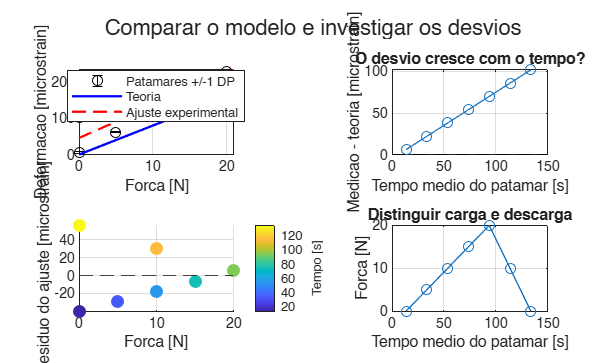

fplot=linspace(0,max(F)*1.05,150);
figure('Name','Medicao e teoria','Color','w');
tiledlayout(2,2,'TileSpacing','compact');
nexttile;
errorbar(F,e,s,'ko','LineStyle','none'); hold on;
plot(fplot,Sref*fplot,'b-','LineWidth',1.4);
plot(fplot,polyval(p0,fplot),'r--','LineWidth',1.3);
grid on; xlabel('Forca [N]'); ylabel('Deformacao [microstrain]');
legend('Patamares +/-1 DP','Teoria','Ajuste experimental','Location','best');
nexttile;
plot(tm,rtheory0,'o-'); yline(0,'k--'); grid on;
xlabel('Tempo medio do patamar [s]'); ylabel('Medicao - teoria [microstrain]');
title('O desvio cresce com o tempo?');
nexttile;
scatter(F,rfit0,60,tm,'filled'); yline(0,'k--'); grid on;
xlabel('Forca [N]'); ylabel('Residuo do ajuste [microstrain]');
cb=colorbar; cb.Label.String='Tempo [s]';
nexttile;
plot(tm,F,'o-'); grid on;
xlabel('Tempo medio do patamar [s]'); ylabel('Forca [N]');
title('Distinguir carga e descarga');
sgtitle('Comparar o modelo e investigar os desvios');

## 6. Cenario opcional: corrigir uma deriva assumida linear

Existem dois patamares confirmados SEM CARGA, um no inicio e um no fim. A interpolacao entre os seus residuos estima uma linha de base temporal. HIPOTESE EXPLICITA: deriva linear, sem deformacao permanente e sem histerese residual. A correcao nao demonstra que estas hipoteses sao reais.

assert(abs(F(1))<0.1 && abs(F(end))<0.1, ...
    'A correcao exige patamares inicial e final confirmados sem carga.');
zini=e(1)-Sref*F(1); zfim=e(end)-Sref*F(end);
deriva=interp1([tm(1);tm(end)],[zini;zfim],tm,'linear');
ecorr=e-deriva;
p1=polyfit(F,ecorr,1); S1=p1(1); q1=p1(2);
assert(S1>0,'Sensibilidade corrigida invalida.');
E1=braco*c/(I*S1*1e-6);
rfit1=ecorr-polyval(p1,F);
R21=1-sum(rfit1.^2)/sum((ecorr-mean(ecorr)).^2);
RMSEfit1=sqrt(mean(rfit1.^2));
RMSEtheory1=sqrt(mean((ecorr-etheory).^2));
fprintf('Deriva estimada = %.6f microstrain/s\n',(zfim-zini)/(tm(end)-tm(1)));

Deriva estimada = 0.800093 microstrain/s


fprintf('Apos correcao assumida: E = %.4f GPa\n',E1/1e9);

Apos correcao assumida: E = 70.0007 GPa


## 7. Comparar ANTES e DEPOIS com o mesmo modelo de referencia

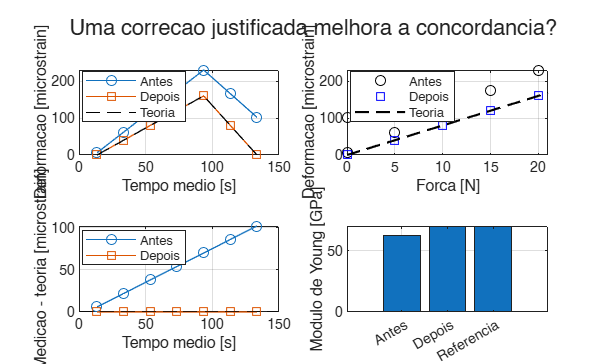

figure('Name','Antes e depois da correcao de deriva','Color','w');
tiledlayout(2,2,'TileSpacing','compact');
nexttile;
plot(tm,e,'o-',tm,ecorr,'s-',tm,etheory,'k--'); grid on;
xlabel('Tempo medio [s]'); ylabel('Deformacao [microstrain]');
legend('Antes','Depois','Teoria','Location','best');
nexttile;
plot(F,e,'ko',F,ecorr,'bs'); hold on;
plot(fplot,Sref*fplot,'k--','LineWidth',1.3); grid on;
xlabel('Forca [N]'); ylabel('Deformacao [microstrain]');
legend('Antes','Depois','Teoria','Location','best');
nexttile;
plot(tm,e-etheory,'o-',tm,ecorr-etheory,'s-'); yline(0,'k--'); grid on;
xlabel('Tempo medio [s]'); ylabel('Medicao - teoria [microstrain]');
legend('Antes','Depois','Location','best');
nexttile;
bar([E0 E1 Eref]/1e9); xticklabels({'Antes','Depois','Referencia'});
ylabel('Modulo de Young [GPa]'); grid on;
sgtitle('Uma correcao justificada melhora a concordancia?');

## 8. Quantificar a comparacao

Etapa={'Antes da correcao de deriva';'Depois da correcao assumida'};
comparacao=table(Etapa,[S0;S1],[q0;q1],[E0;E1]/1e9, ...
    [R20;R21],[RMSEfit0;RMSEfit1],[RMSEtheory0;RMSEtheory1], ...
    'VariableNames',{'Etapa','Sensibilidade_ue_N','Intercepto_ue','E_GPa', ...
    'R2','RMSE_ajuste_ue','RMSE_teoria_ue'});
disp(comparacao);

                 Etapa                 Sensibilidade_ue_N    Intercepto_ue    E_GPa       R2       RMSE_ajuste_ue    RMSE_teoria_ue
    _______________________________    __________________    _____________    ______    _______    ______________    ______________

    {'Antes da correcao de deriva'}          8.9532               45.837      62.547    0.79678         31.313            62.777   
    {'Depois da correcao assumida'}          7.9999           0.00022306      70.001          1       0.005438         0.0054881   



## 9. Sensibilidade da estimativa de E ao erro na espessura

Manter a sensibilidade experimental S1; alterar a espessura ASSUMIDA. E estimado = 6*(L-xg)/(b*h^2*S1*1e-6), logo E ~ 1/h^2.

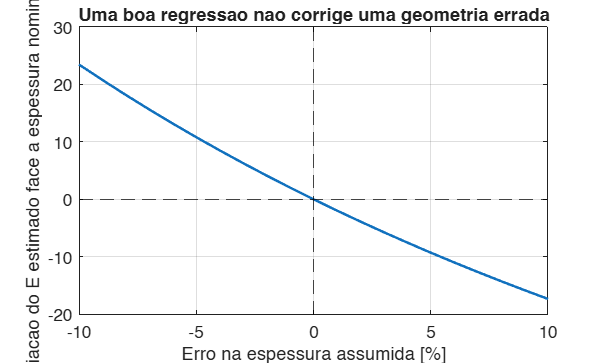

erro_h=(-10:1:10)';
hassumida=h*(1+erro_h/100);
Eesp=6*braco./(b*hassumida.^2*S1*1e-6);
figure('Name','Erro geometrico','Color','w');
plot(erro_h,100*(Eesp/E1-1),'LineWidth',1.5); hold on;
yline(0,'k--'); xline(0,'k--'); grid on;
xlabel('Erro na espessura assumida [%]');
ylabel('Variacao do E estimado face a espessura nominal [%]');
title('Uma boa regressao nao corrige uma geometria errada');

fprintf('Espessura +5%% -> E varia %+.2f %%\n',100*((1.05)^(-2)-1));

Espessura +5% -> E varia -9.30 %


fprintf('Espessura -5%% -> E varia %+.2f %%\n',100*((.95)^(-2)-1));

Espessura -5% -> E varia +10.80 %


## 10. Exportar e escrever a conclusao

patamares=T;
patamares.Deformacao_teorica_ue=etheory;
patamares.Linha_base_estimada_ue=deriva;
patamares.Deformacao_corrigida_ue=ecorr;
patamares.Desvio_antes_ue=e-etheory;
patamares.Desvio_depois_ue=ecorr-etheory;
writetable(comparacao,fullfile(pasta,'exemplo3_comparacao.csv'));
writetable(patamares,fullfile(pasta,'exemplo3_patamares.csv'));
save(fullfile(pasta,'exemplo3_resultados.mat'),'T','patamares','comparacao', ...
    'L','b','h','xg','Eref','I','p0','p1','E0','E1');